# Audio Feature Extraction

- ข้อมูลเสียงแบบ mono ที่ sampling rate 48 kHz ความยาว 1 วินาทีจะมีข้อมูลถึง 48,000 ตัวเลข

- ถ้านับแต่ละตัวเป็น feature หรือลักษณะเฉพาะ ก็นับได้เป็น 48,000 feature

- ข้อมูลเสียงในตัวอย่างนี้ sample ส่วนใหญ่ไม่ได้เป็นตัวบ่งชี้ปัญหาของเครื่องจักร

- การสกัด feature ที่เหมาะสมจึงเป็นกระบวนการที่สำคัญ

## สิ่งที่ควรพิจารณาในการเลือกลักษณะเฉพาะที่จะใช้

- จำนวน feature หรือ dimension

- ความเกี่ยวข้องกับลักษณะปัญหา

Fs = 48000;

audioFile1 = "Examples/Example1.wav";
audioFile2 = "Examples/Example2.wav";
audioFile3 = "Examples/Cycle1.wav";
audioFile4 = "Examples/Cycle2.wav";

[samples, Fs] = audioread(audioFile1);

signalTime = 0.025; % total time in seconds
t = linspace(0, signalTime, round(signalTime * Fs));

testSignal1 = sin(2 * pi * 100 * t);
testSignal2 = cos(2 * pi * 1000 * t);
testSignal3 = testSignal1 .* testSignal2;

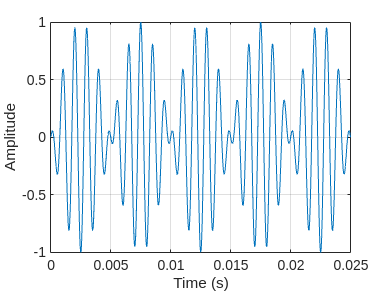

% chunk = samples(1:4800);
% chunk = samples(1:end);
chunk = testSignal3;

% Display the waveform
plot((1:length(chunk))/Fs, chunk);
xlabel("Time (s)");
ylabel("Amplitude");
grid("on");

## Statistical features

- แสดงลักษณะเชิงสถิติในภาพรวมของข้อมูล มักจะใช้ 1 ค่าแทนตัวข้อมูลแต่ละตัวอย่าง

- Mean จะเป็นตัวบอกค่ากลางหรือตำแหน่งศูนย์กลางของข้อมูล สำหรับข้อมูลเสียง ค่านี้มักจะอยู่ใกล้ 0 (ยกเว้นกรณีที่มี DC offset)

- Standard deviation เป็นตัวบอกลักษณะการกระจายตัวของข้อมูล ในแง่ของเสียงอาจเป็นตัวบอกระดับการกระเพื่อมของสัญญาณ

- Root mean square (RMS) มักใช้เป็นตัวประมาณระดับความดังของเสียง ในทางปฏิบัติมักจะใช้แบบ moving RMS ซึ่งจะจัดว่าเป็น time-domain feature

% Normal average and standard deviation
mean(samples)

ans = 0.0041

std(samples)

ans = 0.4287


% Average and standard deviation of absolute values
mean(abs(samples))

ans = 0.3253

std(abs(samples))

ans = 0.2792


% Root mean square value
rms(samples)

ans = 0.4287

## Time-domain features

- ตัว sample เอง

- Moving RMS ใช้เพื่อติดตามความดังของเสียง

windowLength = 480;
% windowLength = round(0.05 * Fs); % t ยิ่งน้อยยิ่งละเอียด

rmsFunc = dsp.MovingRMS(windowLength);


rmsFunc =   dsp.MovingRMS with properties:

                 Method: 'Sliding window'
    SpecifyWindowLength: true
           WindowLength: 480
          OverlapLength: 479


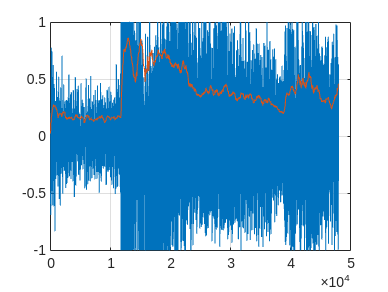

movingRMS = rmsFunc(samples);

plot(samples);
hold on;
plot(movingRMS);
hold off;
grid("on");

% Feature length
length(samples)

ans = 48000

length(movingRMS)

ans = 48000

## Frequency-domain features

- Fast Fourier transform (FFT) -> spectum

- Power spectral density (PSD)

- sample เยอะได้ความถี่ที่ละเอียดขึ้น

### Fast Fourier transform

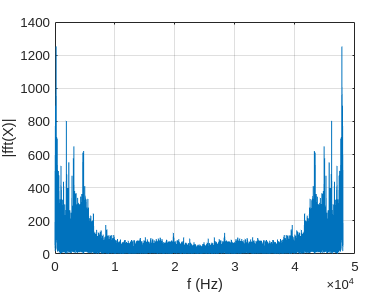

Y = fft(samples);
L = length(Y);
f = (0:L-1) * Fs/L;

plot(f, abs(Y));
xlabel("f (Hz)");
ylabel("|fft(X)|");
grid;

### Single-sided amplitude spectrum

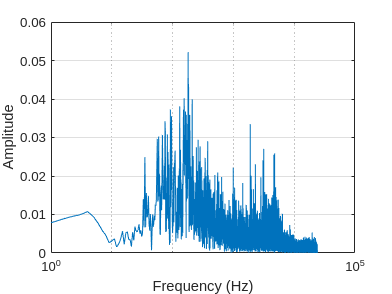

Y = fft(samples);
L = length(Y);
f = (0:L/2) * Fs/L;

P2 = abs(Y/L);    % scale spectrum by length
P1 = P2(1:L/2+1); % remove upper half
P1(2:end-1) = 2 * P1(2:end-1); % doubled as they have complex conjugates

% plot(f, P1);     % use linear frequency scale
semilogx(f, P1); % use logarithmic frequency scale
xlabel("Frequency (Hz)");
ylabel("Amplitude");
grid;

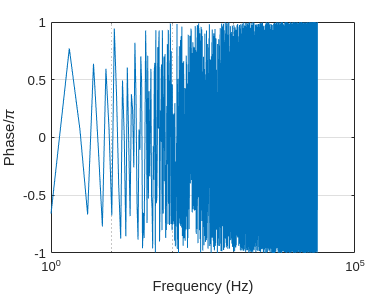

% Phase spectrum
phase = angle(Y);
phase = phase(1:L/2+1);
semilogx(f, phase/pi);
xlabel("Frequency (Hz)");
ylabel("Phase/\pi");
grid;

### Power spectral density

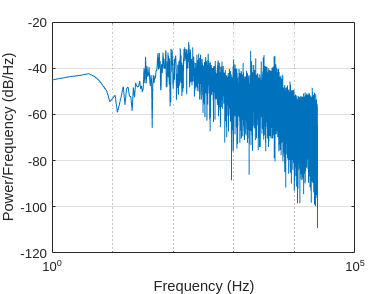

Y = fft(samples);
L = length(Y);
f = (0:L/2) * Fs/L;

Y = Y(1:L/2+1);
psd = (1/(Fs*L)) * abs(Y).^2;
psd(2:end-1) = 2 * psd(2:end-1);

% plot(f, P1);     % use linear frequency scale
semilogx(f, pow2db(psd)); % use logarithmic frequency scale
xlabel("Frequency (Hz)");
ylabel("Power/Frequency (dB/Hz)");
grid;

## Time-frequency features

- Short-time Fourier transform (STFT) and spectrogram

- Mel-frequency cepstral coefficients (MFCC)

- Discrete wavelet transform (DWT)

### STFT

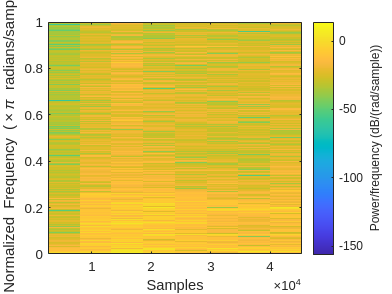

% Basic usage

spec = spectrogram(samples); % alternatively, use stft() function

spectrogram(samples, 'yaxis');


size(spec)

ans =         8193           8


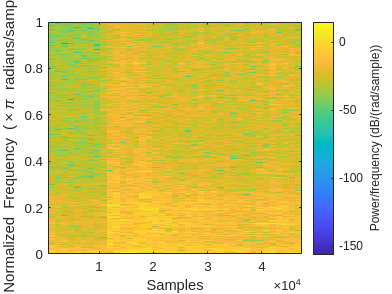

% Advanced usage

windowLength = 2400;
window = hamming(windowLength);
overlap = floor(windowLength/2); % 50% overlap

spec = spectrogram(samples, window, overlap); % alternatively, use stft() function

spectrogram(samples, hamming(windowLength), overlap, 'yaxis');


size(spec)

ans =         2049          39


- ค่าที่ได้จาก `spectrogram()` หรือ `sftf()` เป็น complex อาจต้องแปลงเป็นขนาดด้วย `abs()` ก่อนนำไปใช้เป็น feature ต่อไป

### MFCC

1.Take the [Fourier transform](https://en.wikipedia.org/wiki/Fourier_transform) of (a windowed excerpt of) a signal.

2.Map the powers of the spectrum obtained above onto the [mel](https://en.wikipedia.org/wiki/Mel_scale)[ scale](https://en.wikipedia.org/wiki/Mel_scale), using [triangular overlapping windows](https://en.wikipedia.org/wiki/Window_function) or alternatively, [cosine overlapping windows](https://en.wikipedia.org/wiki/Hann_function).

3.Take the [logs](https://en.wikipedia.org/wiki/Logarithm) of the powers at each of the melfrequencies.

4.Take the [discrete cosine transform](https://en.wikipedia.org/wiki/Discrete_cosine_transform) of the list of mellog powers, as if it were a signal.

5.The MFCCs are the amplitudes of the resulting spectrum.

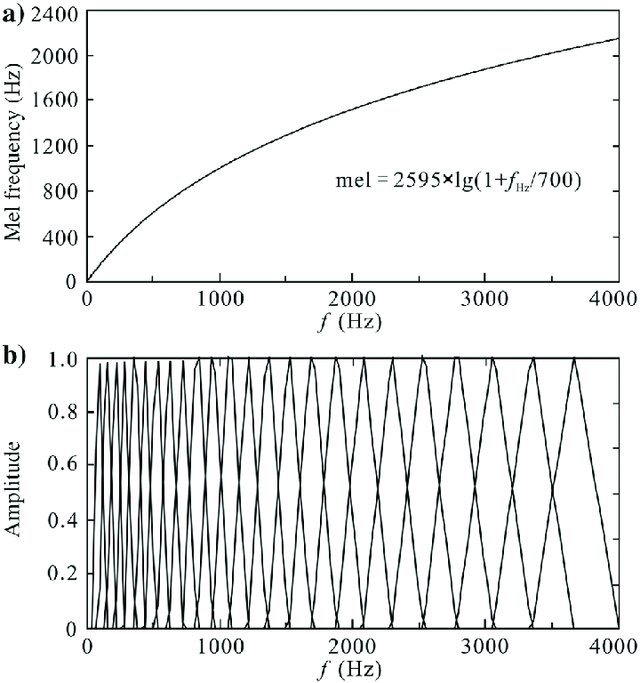

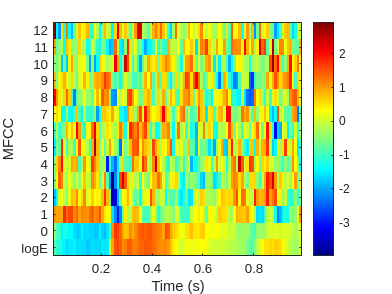

% Basic usage

coeffs = mfcc(samples, Fs);

mfcc(samples, Fs);


size(coeffs)

ans =     98    14


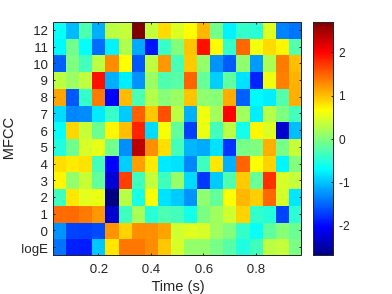

% Advanced usage

windowLength = 4800;
window = hann(windowLength, "periodic");
overlap = floor(windowLength/2); % 50% overlap

coeffs = mfcc(samples, Fs, 'Window', window, 'OverlapLength', overlap);

mfcc(samples, Fs, 'Window', window, 'OverlapLength', overlap);


size(coeffs)

ans =     19    14


### DWT

#### Dauberchies analysis wavelets

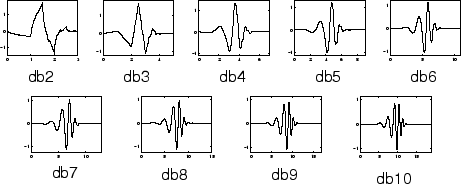

Source: [Introduction to Wavelet Families - MATLAB & Simulink](https://www.mathworks.com/help/wavelet/gs/introduction-to-the-wavelet-families.html)

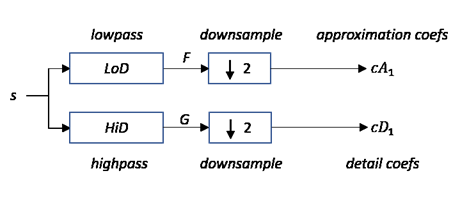

% First levels

[cA, cD] = dwt(samples, 'db2');

length(cA)

ans = 24001

length(cD)

ans = 24001

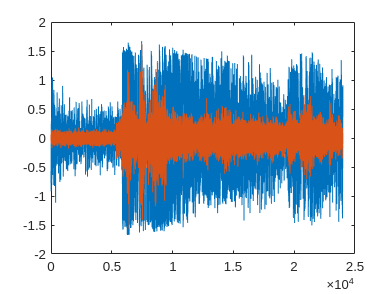


plot(cA);
hold on;
plot(cD);
hold off;

[cA1, cD1] = dwt(cA, 'db2');

length(cA1)

ans = 12002

length(cD1)

ans = 12002

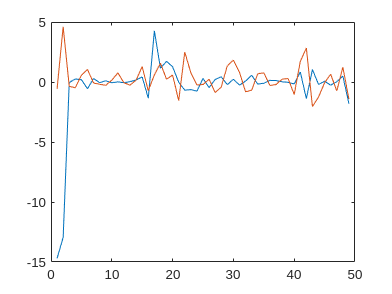


[cA2, cD2] = dwt(cA1, 'db2');
[cA3, cD3] = dwt(cA2, 'db2');
[cA4, cD4] = dwt(cA3, 'db2');
[cA5, cD5] = dwt(cA4, 'db2');
[cA6, cD6] = dwt(cA5, 'db2');
[cA7, cD7] = dwt(cA6, 'db2');
[cA8, cD8] = dwt(cA7, 'db2');
[cA9, cD9] = dwt(cA8, 'db2');

plot(cA9);
hold on;
plot(cD9);
hold off;

## การยุบ feature 2 มิติ

disp(size(spec));

        2049          39



spec = abs(spec);            % convert from complex to magnitude
spec = reshape(spec, 1, []); % flatten the matrix
disp(size(spec));

           1       79911



## การผสมผสาน feature

- Feature จากต่างวิธีอาจมีช่วงของค่าต่างกันมาก โมเดลทำนายบางแบบอาจจะทำงานได้ไม่ดี

- Feature standardization ด้วย z-score เพื่อให้ข้อมูลมีค่าเฉลี่ยเป็น 0 และ standard deviation เป็น 1

- ในกรณีที่ช่วงของค่าไม่ต่างกันมาก อาจไม่จำเป็นต้อง standardize/normalize

reshapedMfcc = reshape(coeffs, 1, []);
combinedDwt = [cA9', cD9'];

combinedFeatures = [normalize(reshapedMfcc), normalize(combinedDwt)];